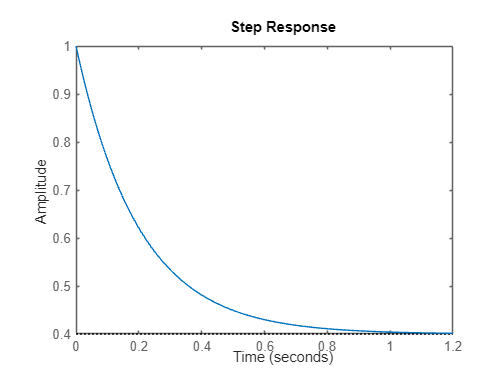

%Aula 9

% %UP ->  overshoot    ->  Ultrapassagem percentual
% Tp  ->  peaktime     ->  Instante de Pico
% Ts  ->  settlingtime ->  Tempo de Acomodação
% Tr  ->  risetime     ->  Tem de Subida

% c(t)= 2/5 + (3/5)e^-5
G = tf([1 2],[1 5]);
step(G)

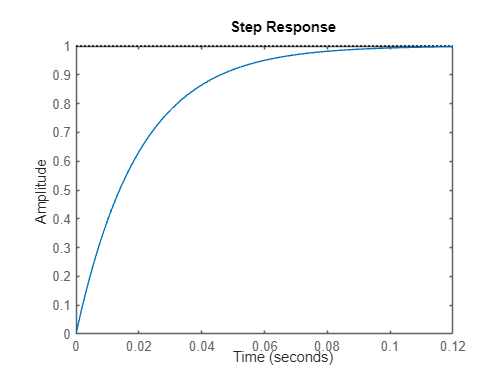


%Exercício 4.2 (Página 10)
G = tf(50,[1 50]);
step(G)

stepinfo(G)

ans = struct with fields:
         RiseTime: 0.0439
    TransientTime: 0.0782
     SettlingTime: 0.0782
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 0.1464


tc=1/50

tc = 0.0200


%Exercicio 1 (Página 11)
g = tf(0.703,[1 0.703])

g =
 
    0.703
  ---------
  s + 0.703
 
Continuous-time transfer function.
Model Properties


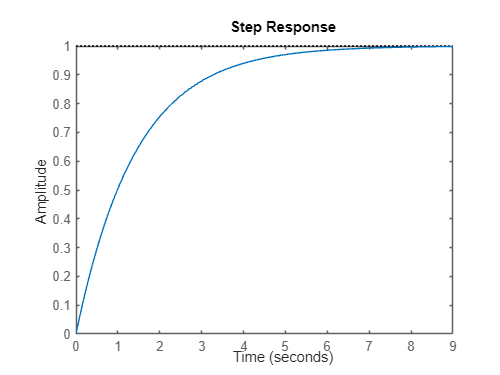

step(g)

stepinfo(g)

ans = struct with fields:
         RiseTime: 3.1252
    TransientTime: 5.5648
     SettlingTime: 5.5648
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 10.4157


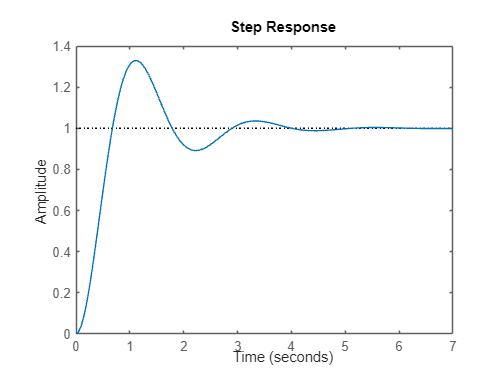


%amortecimento
%Resposta Subamortecida
g = tf(9,[1 2 9]);
step(g)

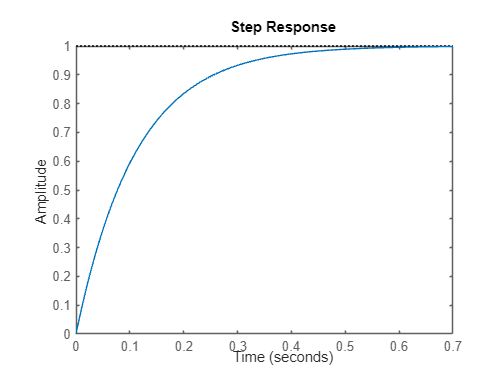


%Resposta Não Amortecida
g = tf(9,[1 9]);
step(g)

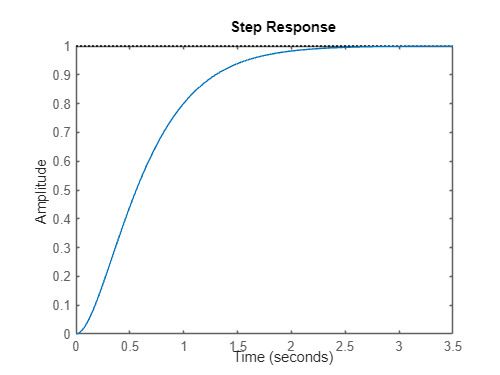


%Resposta Criticamente Amortecida
g = tf(9,[1 6 9]);
step(g)


%Exercício 4.3 (Página 24)
roots([1 12 400]);
%c(t) = A + Be^-(6t)cos(10,08t + O);
roots([1 90 900])

ans =   -78.5410
  -11.4590


%c(t) = A + Be^-(78,54t) + Ce^-(11,46t);
roots([1 30 225]); 
%c(t) = A + Be^-(15t) + Ce^-(15t);
roots([1 0 625]);
%c(t) = A + Bcos(25t + O);

%Exemplo 4.3 (Página 29)
roots([1 4.2 36]);
w = sqrt(36)

w = 6

cidilha = (4.2/2) / w

cidilha = 0.3500

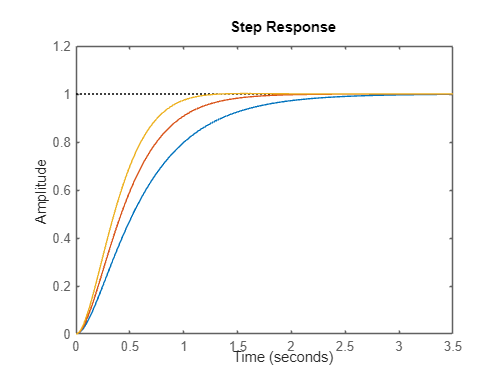


%Exemplo 4.4 (Página 38)
G1 = tf([12],[1 8 12]);
G2 = tf([16],[1 8 16]);
G3 = tf([20],[1 8 20]);
step(G1,G2,G3)

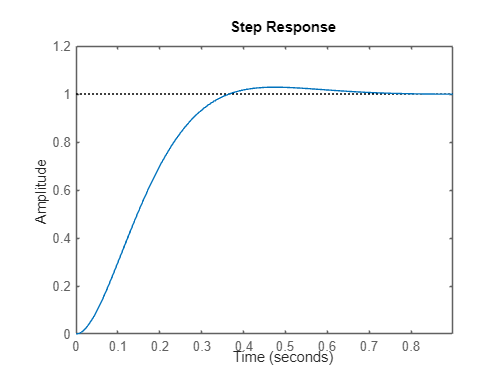


%Exemplo 4.5 (Página 39)
g=tf([100],[1 15 100]);
step(g)

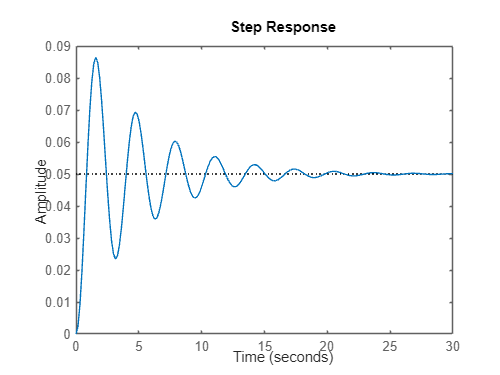


%Exercicio 3 (Página 40)
g1=tf([4],[1 2/5 4]);
step(g1*1/20)